# Fitting the MZI with findpeaks

## Introduction

Manually guessing parameters can be inefficient and error-prone, especially with large datasets. We can instead use a numerical approach to identify spectral features—specifically the minima in the spectrum—which allows us to derive key parameters such as the group index and effective index components. In this exercise, you will apply techniques from the lecture to automate the estimation of initial parameters for curve fitting in optical interferometer data.

MATLAB’s [`findpeaks`](https://www.mathworks.com/help/signal/ref/findpeaks.html) function is a powerful tool for identifying features of your data, even in noisy experimental data. By analyzing the spacing and position of the spectral minima, you can extract values for the free spectral range (FSR), group index, and components of the effective index expansion ($n_1$, $n_2$, and $n_3$). These initial guesses will then be used to improve the robustness and convergence of the curve fitting algorithm.

## Task

Use the Matlab code below to download and plot the measurement data, and curve fit it to the MZI transfer function.

Check your answer when you think you have a good fit. 

Note that two data file examples are provided. Note that the ∆L path length difference must be correctly set.

**Select data to load**

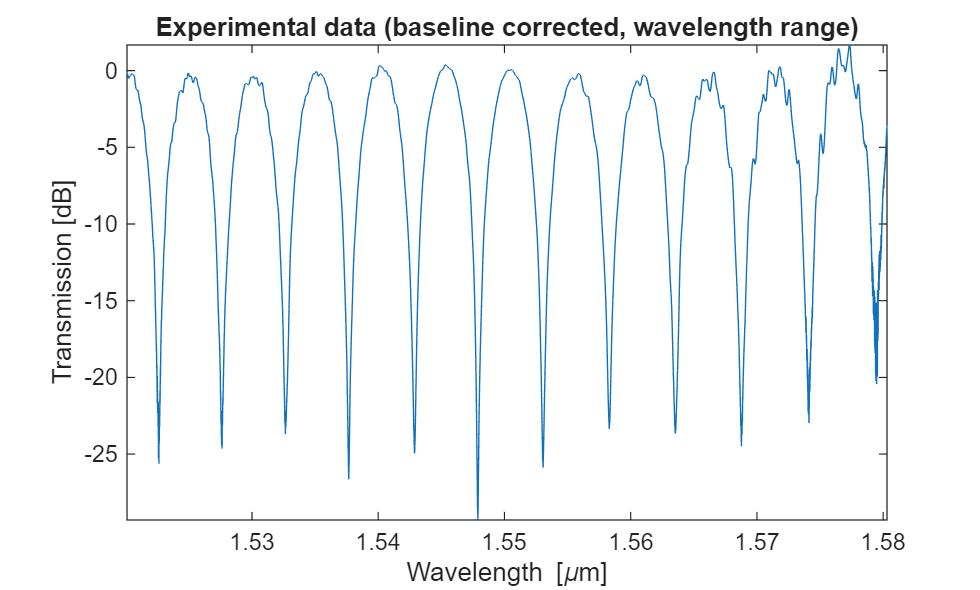

% TE
url = 'https://www.dropbox.com/s/1rvjfef4jqybc12/ZiheGao_MZI2_271_Scan1.mat?dl=1';
dL = 111.915;  % [micron] Path length difference in the MZI

% TM:
%url = 'https://www.dropbox.com/s/onjwrarapf6dumv/ADCL_1_1153_Scan1_L2-L1%3D100um.mat?dl=1';
%dL = 100;

PORT=1; % Which Fibre array port is the output connected to?

% Data is stored in variable "scanResults".
% There are two columns - wavelength (1), and amplitude (2)
lambda=scanResults(1,PORT).Data(:,1)/1e9;
amplitude=scanResults(1,PORT).Data(:,2);

% Curve fit data to a polynomial for baseline correction
p=polyfit((lambda-mean(lambda))*1e6, amplitude, 4);
amplitude_baseline=polyval(p,(lambda-mean(lambda))*1e6); 

% Perform baseline correction to flatten the spectrum
% Use the curve polynomial, and subtract from original data
amplitude_corrected = amplitude - amplitude_baseline;
amplitude_corrected = amplitude_corrected + max(amplitude_baseline) - max(amplitude);

% data only within the wavelength range of interest.
lambda_min = min(lambda);	% Can limit the analysis to a range of wavelengths
lambda_max = max(lambda);   %  if the data on the edges is noisy
lambda1=lambda_min:min(diff(lambda)):lambda_max;
amplitude=interp1(lambda, amplitude_corrected, lambda1,'linear');
lambda=lambda1;
amplitude(find(amplitude==-inf))=-50;  % check if there are -infinity data points

% plot baseline corrected spectrum
figure;
plot (lambda*1e6, amplitude);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('Experimental data (baseline corrected, wavelength range)');

**Find peaks, extract FSR and ng, and neff as initial parameters**

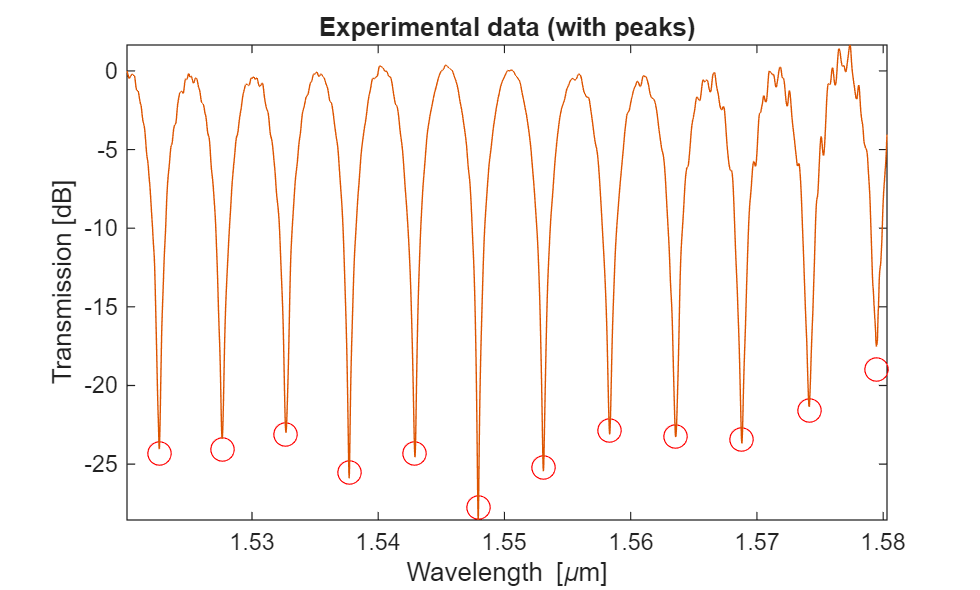

% smooth (0.1% moving average filter)
windowSize = floor(1e-3*length(lambda)); b = (1/windowSize)*ones(1,windowSize);
amplitude_smooth=filter(b,1,amplitude);

% FIND PEAKS
[pks,x_values,w,p]=findpeaks(-amplitude_smooth, lambda, 'minPeakProminence',4,'Annotate','extents');

% plot spectrum with peaks
figure;
plot (x_values*1e6, interp1(lambda, amplitude, x_values,'pchip'), 'ro','MarkerSize',10); 
hold on
plot (lambda*1e6, amplitude_smooth);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('Experimental data (with peaks)');


% Calculate and plot ng data points from FSR
lambda_ng = (x_values(1:end-1)+x_values(2:end))/2;
FSR=(x_values(2:end)-x_values(1:end-1));
ng = abs(lambda_ng.^2/1/(dL*1e-6)./FSR);
% find average ng from all reasonable ng values:
indexes = find(gt(ng,3)); ng=ng(indexes); lambda_ng = lambda_ng(indexes); FSR = FSR(indexes);
indexes = find(lt(ng,5)); ng=ng(indexes); lambda_ng = lambda_ng(indexes); FSR = FSR(indexes);
ng_av = mean(ng);
if eq(length(ng),0)
  disp ('No group index values found.  Terminating script.');
  return
end
disp (['(estimate) Group index: ' num2str(ng_av)])

(estimate) Group index: 4.1617


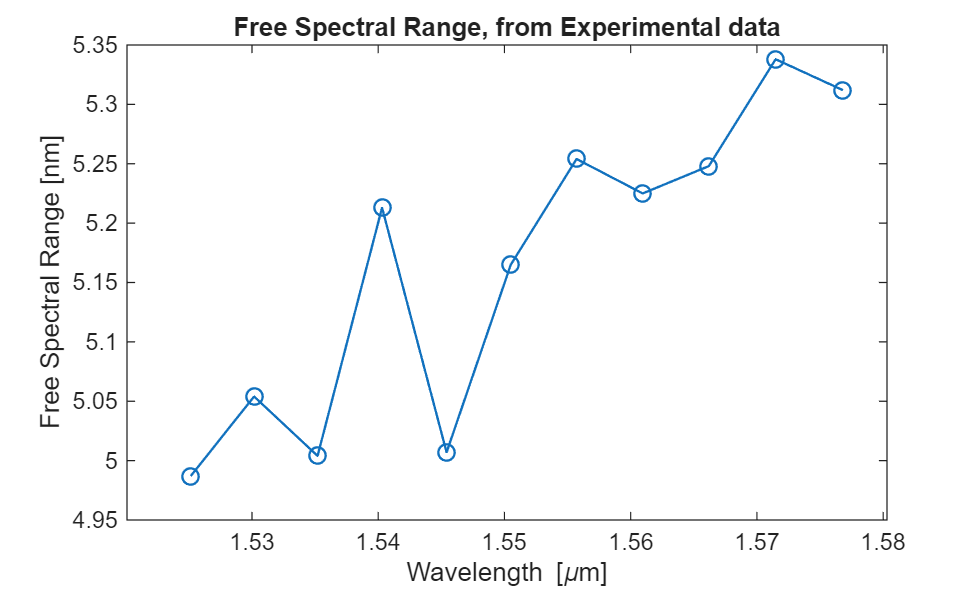


% plot FSR
figure;
plot (lambda_ng*1e6, FSR*1e9, '-o','LineWidth',1,'MarkerSize',7 );
xlabel ('Wavelength [\mum]')
ylabel ('Free Spectral Range [nm]')
xlim([min(lambda), max(lambda)]*1e6);
title ('Free Spectral Range, from Experimental data');


% plot ng
figure
plot (lambda_ng*1e6, ng, '-o','LineWidth',1,'MarkerSize',7 )
xlabel ('Wavelength [\mum]')
ylabel ('Group Index')
xlim([min(lambda), max(lambda)]*1e6);
title ('Waveguide Group Index, from Experimental data');


% find starting point for curve fitting MZI, using the ng data
% Part 1 - n1
% lambda0 is in microns.
lambda0 = x_values(floor(length(x_values)/2)) * 1e6;
n1_initial=2.4;
modeNumber = n1_initial * dL / lambda0 - 0.5;
n1 = (2*floor(modeNumber)+1)*lambda0/2/dL;

% Part 1 - n2 from ng_av
n2 = (n1-ng_av)/lambda0;

% Part 3 - n3 from slope of ng vs. lambda, to get the dispersion
f_line = @(x,xdata)x(2)*xdata+x(1);
[xfit,resnorm]  = lsqcurvefit(f_line,[ng_av 0],lambda_ng*1e6,ng);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


r=corrcoef(ng,f_line(xfit, lambda_ng*1e6));
r2_ng=r(1,2).^2;
disp (['Goodness of fit, r^2 value: ' num2str(r2_ng)] )

Goodness of fit, r^2 value: 2.4662e-05


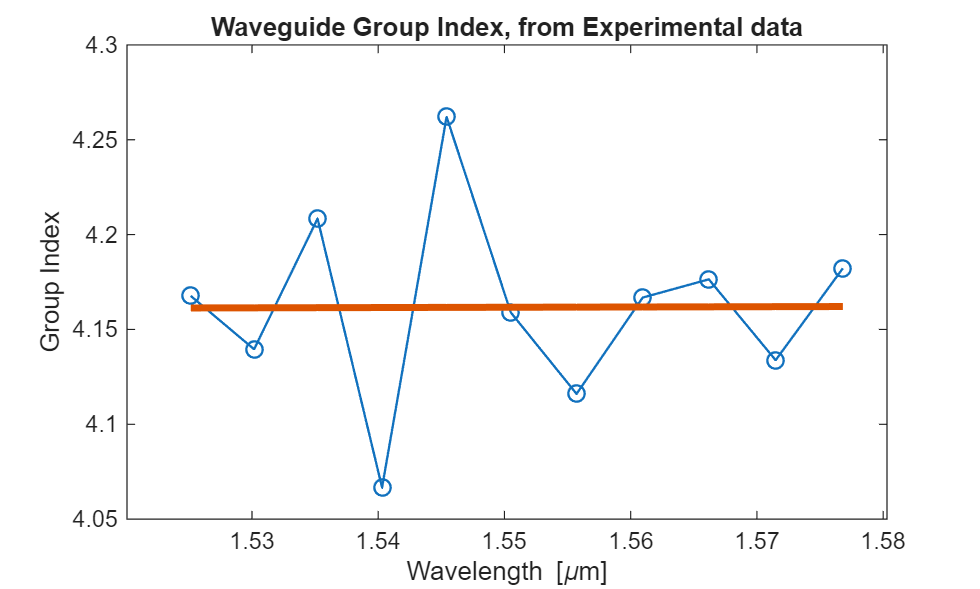

hold all;
plot (lambda_ng*1e6, f_line(xfit, lambda_ng*1e6),'LineWidth',3)

n3 = -xfit(2)/2/lambda0;
Dispersion0 = -(lambda0*1e-6) / 299792458 * 2* (n3*1e12) * 1e12 /1e9 /1e-3;     	
disp (['(estimate from ng slope) Dispersion [ps/nm/km]: ' num2str(Dispersion0) ])

(estimate from ng slope) Dispersion [ps/nm/km]: 48.6981



if lt(r2_ng,0.01)   % only use the result if the fit is good
  n3 = 0;
end

% Initial conditions for fitting:
nx_init = [n1 n2 n3];
alpha_init = 1e-3;  % propagation loss [micron^-1]
x0=[nx_init, alpha_init, 0];

#### **Define the MZI transfer function**

- as a Taylor expansion around the central wavelength

- Use units of [microns] – keeps the variables closer to 1.

- These make the curve fitting easier.

- use Matlab anonymous functions

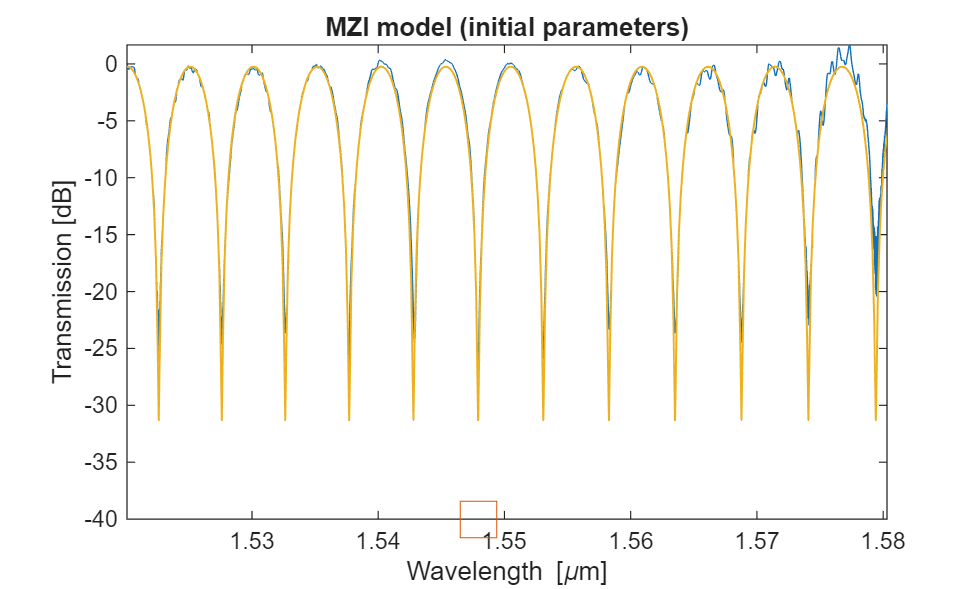

% effective index:
neff = @(nx, lambda) ...
		(nx(1) + nx(2).*(lambda-lambda0) + nx(3).*(lambda-lambda0).^2); 
% neff([2.4, -1, 0], 1.56)  % test it.
% alpha = 1e-3;  % propagation loss [micron^-1]

% complex propagation constant
beta = @(nx, alpha, lambda) ...
		(2*pi*neff(nx, lambda)./lambda - 1i*alpha/2*ones(1,length(lambda)) );
% beta([2.4, -1, 0], 1e-3, [1.56, 1.57]) % test it.

% MZI transfer function
T_MZI = @(X, lambda) ...
        (10*log10( 0.25* abs(1+exp(-1i*beta(X(1:3), X(4), lambda)*dL)).^2) +X(5) );
% T_MZI([2.4, -1, 0, 1e-3], [1.56, 1.57]) % test it.


figure;
plot (lambda*1e6, amplitude);
hold all;
plot (lambda0, -40,'s','MarkerSize',20);
plot(lambda*1e6, T_MZI(x0, lambda*1e6),'-','LineWidth',2);
xlabel ('Wavelength [\mum]');

ylabel ('Transmission [dB]');
axis tight
title ('MZI model (initial parameters)');


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


xfit =     2.3997   -1.1375    0.0176    0.0025    0.4592


**Curve fit**

[xfit,resnorm] = lsqcurvefit(T_MZI,x0,lambda*1e6,amplitude);
xfit

Goodness of fit, r^2 value: 0.98178


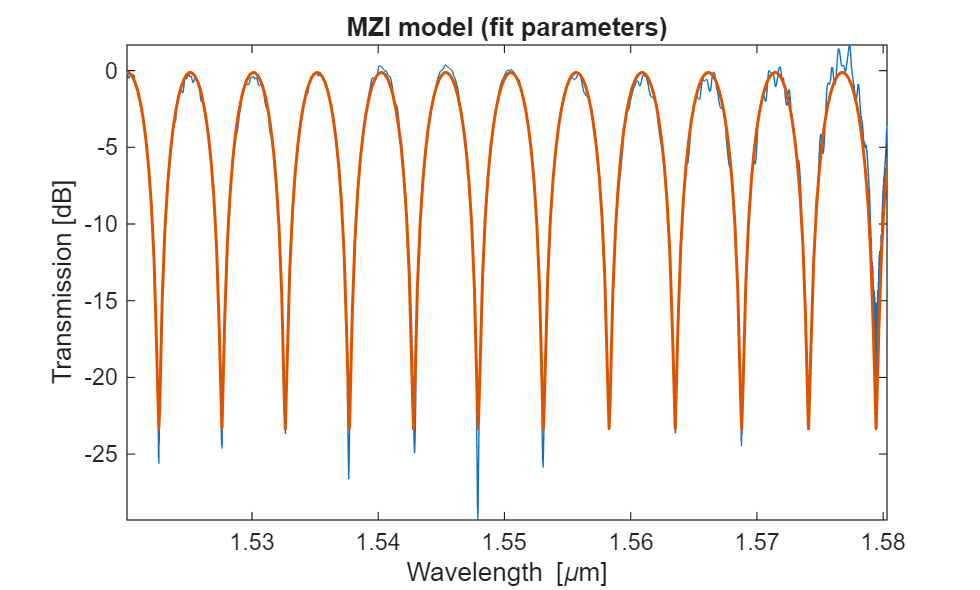

r=corrcoef(amplitude,T_MZI(xfit, lambda*1e6));
r2=r(1,2).^2;
disp (['Goodness of fit, r^2 value: ' num2str(r2) ])

figure;
plot (lambda*1e6, amplitude);
hold all;
plot(lambda*1e6, T_MZI(xfit, lambda*1e6),'LineWidth',3); 
xlabel ('Wavelength [\mum]');

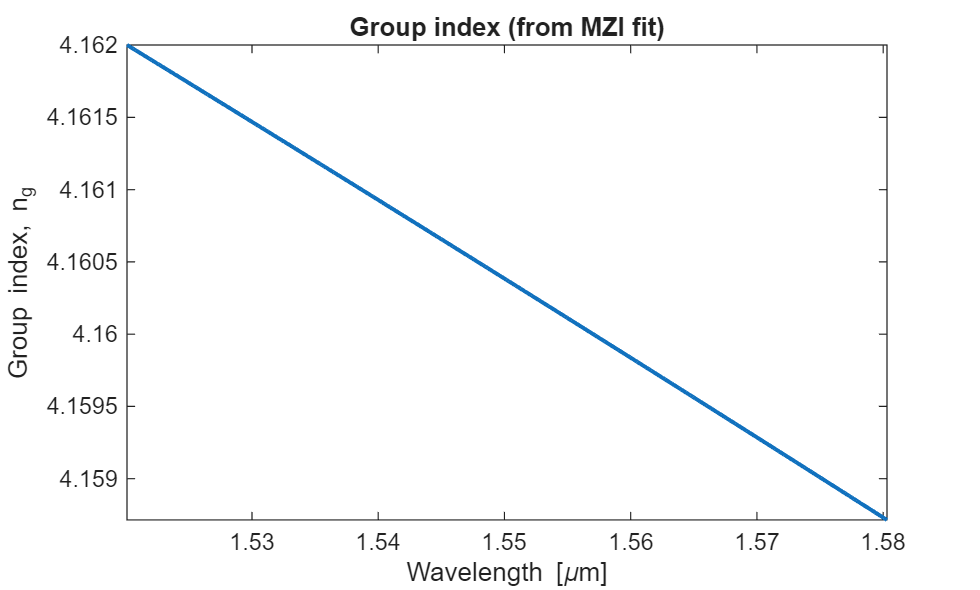

Waveguide parameters at wavelength [um]: 1.5479


Group index: 4.1605


Dispersion [ps/nm/km]: -181.8502


ylabel ('Transmission [dB]');
axis tight
title ('MZI model (fit parameters)');

% Check if the fit is good.  If so, find ng
if (ge(r2,0.8))
  % plot ng curve
  figure;
  neff_fit = neff(xfit(1:3),lambda*1e6);
  dndlambda=diff(neff_fit)./diff(lambda); dndlambda=[dndlambda, dndlambda(end)];
  ng=(neff_fit - lambda .* dndlambda);
  plot(lambda*1e6, ng, 'LineWidth',4);
  xlabel ('Wavelength [\mum]');
  ylabel ('Group index, n_g');
  axis tight
  title ('Group index (from MZI fit)');
    
  % waveguide parameters at lambda0
  disp (['Waveguide parameters at wavelength [um]: ' num2str(lambda0)])
  ng0 = xfit(1) - lambda0*xfit(2);
  disp (['Group index: ' num2str(ng0)])

  % Dispersion:
  c=299792458;	
  Dispersion0 = -(lambda0*1e-6) / c * 2* (xfit(3)*1e12);  % [s/m^2]
  % [ps/nm/km]: 
  Dispersion0 = Dispersion0 * 1e12 /1e9 /1e-3;

  disp (['Dispersion [ps/nm/km]: ' num2str(Dispersion0) ])
  
end

## Check your work

if exist('r2')
    assert(ge(r2,0.8), 'The goodness-of-fit is low.  The R^2 value should be greater than 0.8.  Adjust the initial conditions until the fit quality is higher.')
    if ge(r2,0.8)
        disp('Fitting seems good.');
    end

Fitting seems good.


else
    assert(0, 'Fitting not performed. Make sure you have a variable named r2')
end        

Error using assert
Looks like you just ran the code without changing the data file.  Try plotting a different data file.


url0 = 'https://www.dropbox.com/s/1rvjfef4jqybc12/ZiheGao_MZI2_271_Scan1.mat?dl=1';
assert(not(strcmp(url0, url)), 'Looks like you just ran the code without changing the data file.  Try plotting a different data file.');

Lukas Chrostowski, curve fitting the MZI using findpeaks, 2015/08/14